clc ;
clear all ;

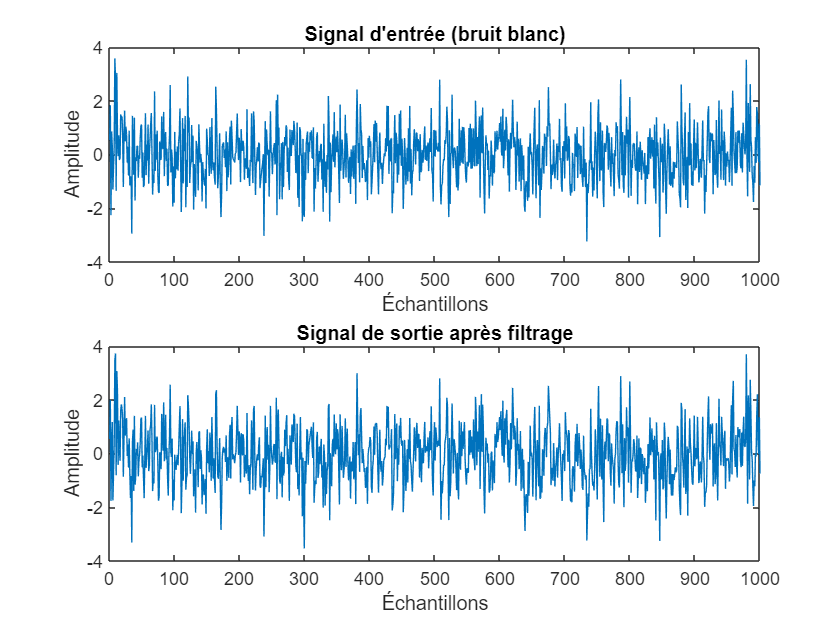


% --Génération de signaux test-- 

N = 1000;  % Number of samples
x = randn(N, 1);  % White noise
h = [1; 0.3; -0.1; 0.2];  % Impulse response of filter
d = filter(h, 1, x);  % Output signal

figure;
subplot(2, 1, 1);
plot(x);
title('Signal d''entrée (bruit blanc)');
xlabel('Échantillons');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(d);
title('Signal de sortie après filtrage');
xlabel('Échantillons');
ylabel('Amplitude');

%----- Validation de l-algorithme LMS------

P = 4;  % Filter order
mu = 0.01;  % Step-size
[w, y, e] = algolms(x, d, P, )

w =          0         0         0         0    0.0019    0.0094    0.0512    0.0576    0.0594    0.2986    0.4527    0.4667    0.6095    0.6236    0.6238    0.6262    0.6263    0.6266    0.6426    0.6611    0.6754    0.6774    0.6898    0.6909    0.7107    0.7130    0.7175    0.7201    0.7209    0.7209    0.7242    0.7278    0.7331    0.7412    0.7448    0.7850    0.7948    0.7972    0.7990    0.8038    0.8127    0.8130    0.8132    0.8140    0.8145    0.8172    0.8172    0.8172    0.8190    0.8241
         0         0         0         0   -0.0049    0.0154    0.0052    0.0244    0.0222    0.0451    0.2442    0.2154    0.1519    0.2110    0.2089    0.2087    0.2083    0.2087    0.2074    0.2269    0.2411    0.2455    0.2386    0.2368    0.2455    0.2531    0.2553    0.2589    0.2570    0.2570    0.2557    0.2526    0.2484    0.2571    0.2618    0.2729    0.2529    0.2636    0.2629    0.2602    0.2531    0.2577    0.2578    0.2572    0.2577    0.2568    0.2580    0.2580    0.2575    0

y =          0
         0
         0
         0
   -0.0105
   -0.1504
    0.0470
    0.1490
    0.1200
    0.9401


e =          0
         0
         0
    0.1087
    1.1806
   -1.5997
   -0.7324
    0.2580
    3.3430
    2.7819


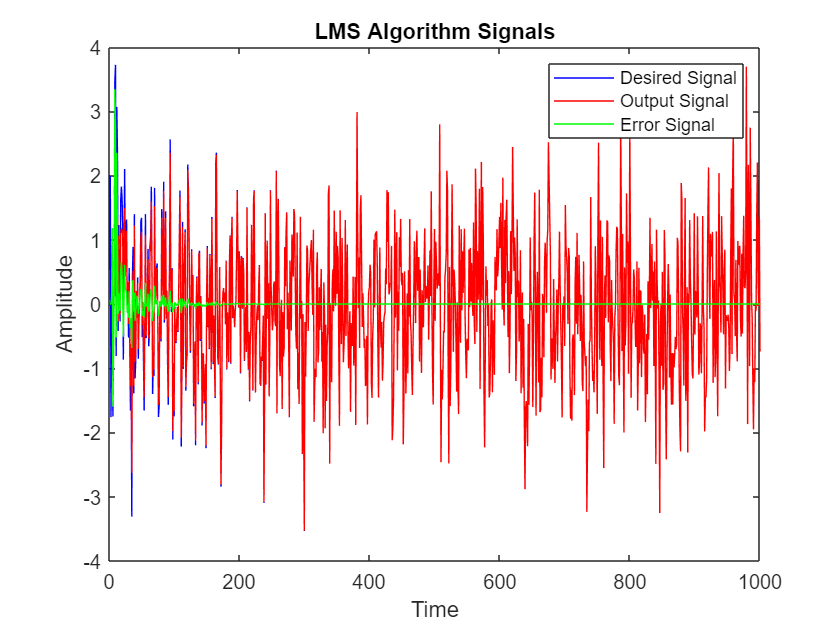


figure;
plot(1:N, d, 'b', 1:N, y, 'r', 1:N, e, 'g');
legend('Desired Signal', 'Output Signal', 'Error Signal');
xlabel('Time'); ylabel('Amplitude'); 
title('LMS Algorithm Signals');

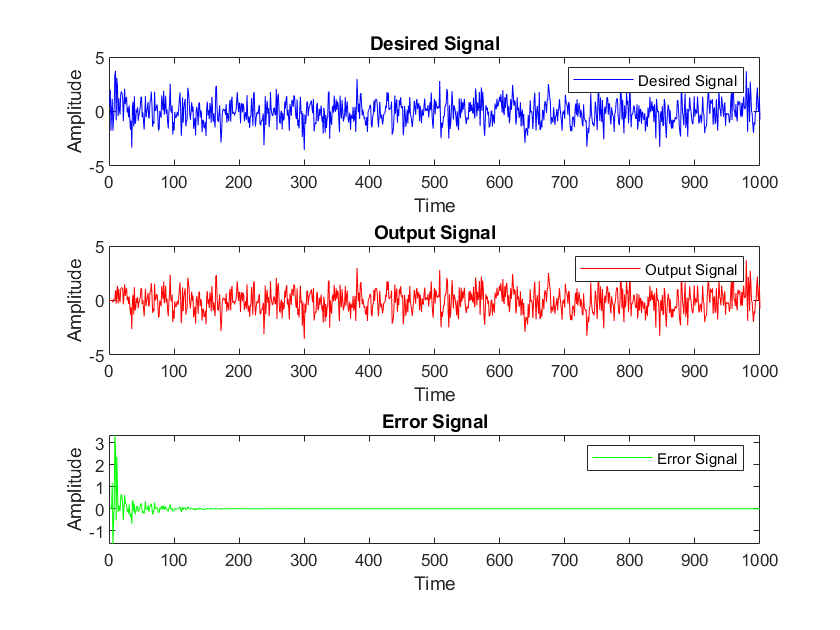


figure;

% First subplot: Desired Signal
subplot(3,1,1);  % 3 rows, 1 column, 1st plot
plot(1:N, d, 'b');
legend('Desired Signal');
xlabel('Time'); ylabel('Amplitude'); 
title('Desired Signal');

% Second subplot: Output Signal
subplot(3,1,2);  % 3 rows, 1 column, 2nd plot
plot(1:N, y, 'r');
legend('Output Signal');
xlabel('Time'); ylabel('Amplitude'); 
title('Output Signal');

% Third subplot: Error Signal
subplot(3,1,3);  % 3 rows, 1 column, 3rd plot
plot(1:N, e, 'g');
legend('Error Signal');
xlabel('Time'); ylabel('Amplitude'); 
title('Error Signal');

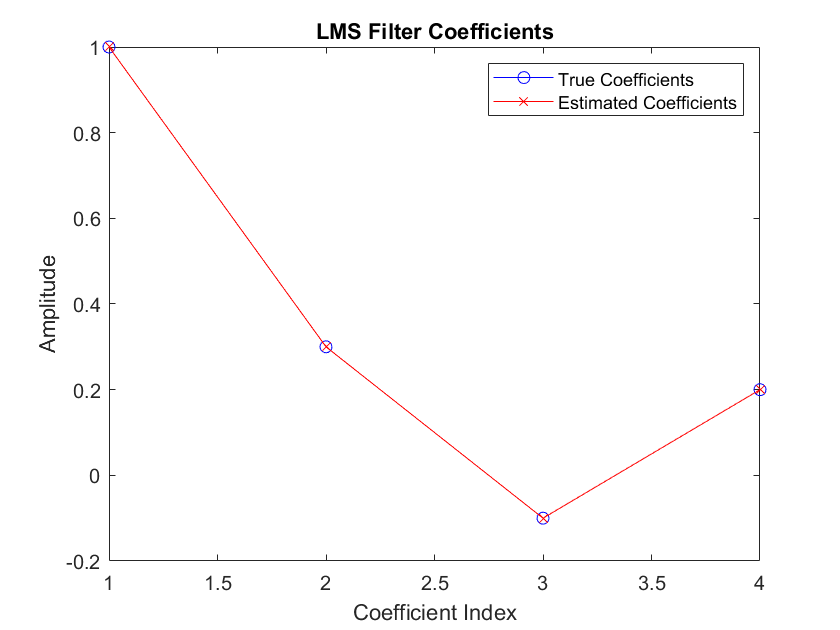



% Plot true and estimated filter coefficients
figure;
plot(1:P, h, 'bo-', 1:P, w(:, end), 'rx-');
legend('True Coefficients', 'Estimated Coefficients');
xlabel('Coefficient Index'); ylabel('Amplitude'); 
title('LMS Filter Coefficients');

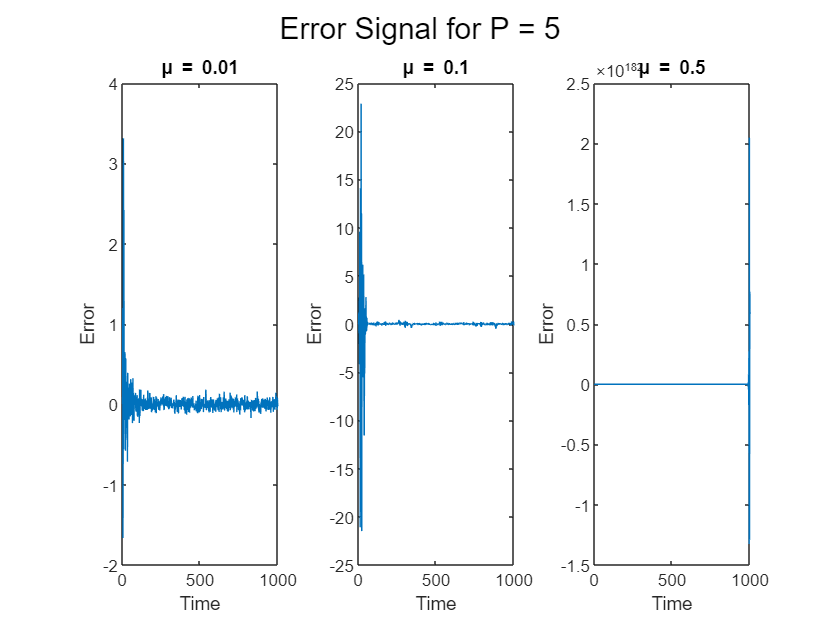

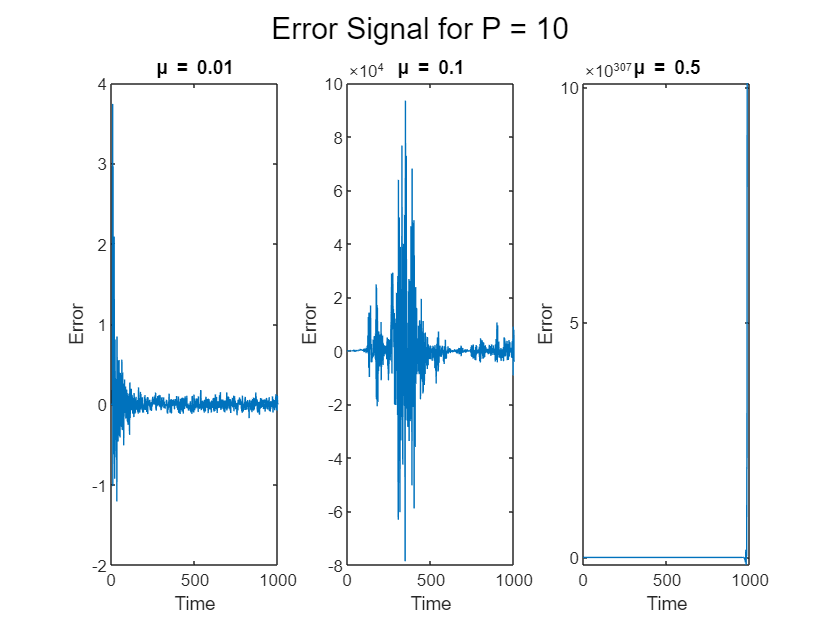

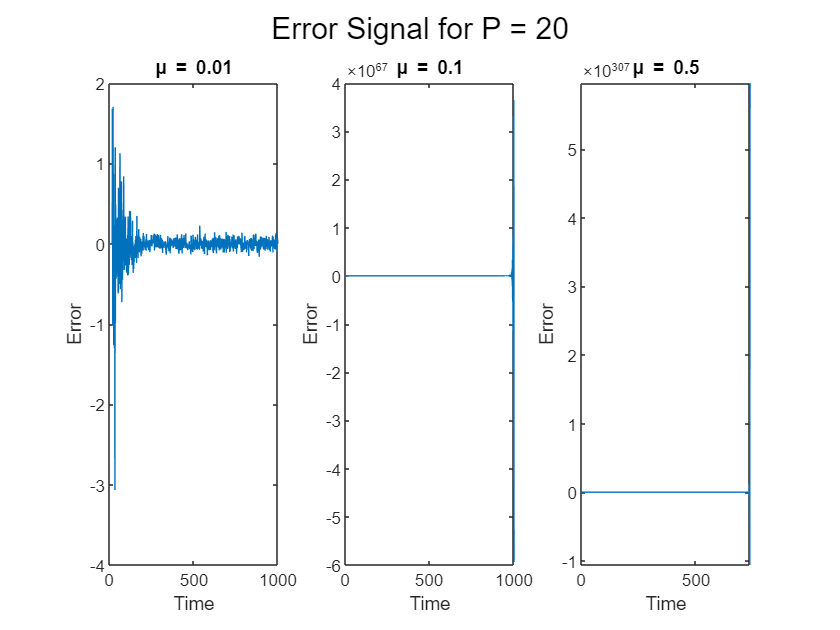

%-----Test de l-algorithme LMS----

noise = 0.05 * randn(N, 1);  % Add noise
d_noisy = d + noise;

% Test for different filter lengths and step sizes
P_values = [5, 10, 20];
mu_values = [0.01, 0.1, 0.5];

for P_idx = 1:length(P_values)
    P = P_values(P_idx);
    figure; % Create a new figure for each P
    
    for mu_idx = 1:length(mu_values)
        mu = mu_values(mu_idx);
        
        % Apply the LMS algorithm
        [w, y, e] = algolms(x, d_noisy, P, mu);
        
        % Create subplot for the current mu
        subplot(1, 3, mu_idx);
        plot(1:N, e);
        
        % Set title and labels for each subplot
        title(['\mu = ', num2str(mu)]);
        xlabel('Time'); ylabel('Error');
    end
    
    % Set overall figure title
    sgtitle(['Error Signal for P = ', num2str(P)]);
end

%--------II.APPLICATION-------

%------ 1) Signal audio avec une voix--------

% Charger le signal vocal
[y, Fs] = audioread('C:\Users\Abdelhamied\Desktop\ENSEA\MATLAB\SA\TP2\Sources\Voix1.wav');

%sound(y, Fs);  % Écouter le signal vocal original

% Charger la réponse impulsionnelle et filtrer le signal
Rep = importdata('C:\Users\Abdelhamied\Desktop\ENSEA\MATLAB\SA\Re_ Sujet TP\Rep.dat');

y_filtered = filter(Rep, 1, y);  % Filtrer le signal

%sound(y_filtered, Fs);  % Écouter le signal filtré

% Ajouter du bruit blanc
noise = 0.05 * randn(length(y_filtered), 1);
y_noisy = y_filtered + noise;

sound(y_noisy, 16000);  % Écouter le signal bruyant

% Annuler l'écho en utilisant LMS
mu = 0.01;  % Définir la taille de pas
[w, y_echo_canceled0, e] = algolms(y_noisy, y, 5, mu);
[w, y_echo_canceled1, e] = algolms(y_noisy, y, 15, mu);
[w, y_echo_canceled2, e] = algolms(y_noisy, y, 50, mu);
[w, y_echo_canceled3, e] = algolms(y_noisy, y, 100, mu);

sound(y_echo_canceled, 2*Fs);

sound(y_noisy, 2*Fs);

warning('off', 'all');  % Turn off all warnings

t = (0:length(y_noisy)-1)/Fs

t =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


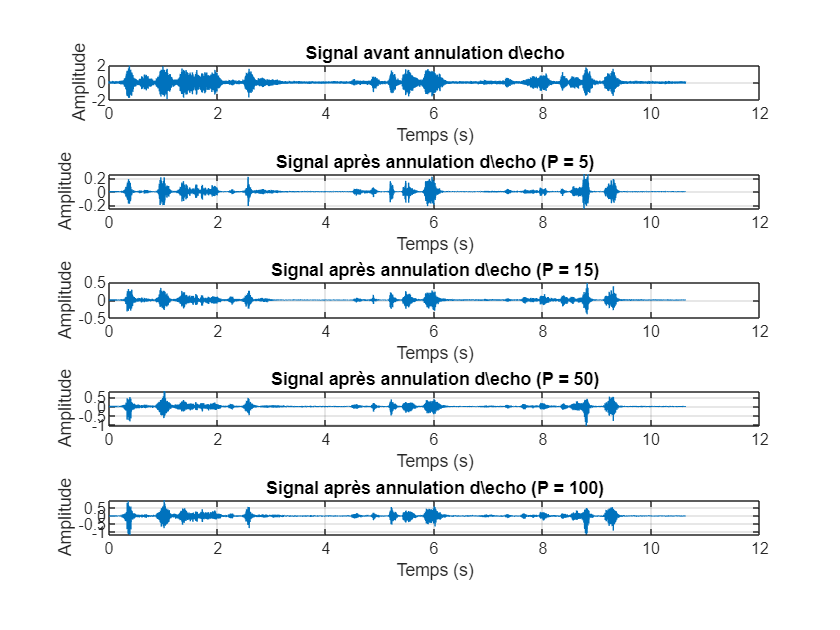


% Plot the signals in subplots
figure;

% Plot original signal (y_noisy)
subplot(5, 1, 1);
plot(t, y_noisy);
title('Signal avant annulation d\echo');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (P = 5)
subplot(5, 1, 2);
plot(t, y_echo_canceled0);
title('Signal après annulation d\echo (P = 5)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (P = 15)
subplot(5, 1, 3);
plot(t, y_echo_canceled1);
title('Signal après annulation d\echo (P = 15)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (P = 50)
subplot(5, 1, 4);
plot(t, y_echo_canceled2);
title('Signal après annulation d\echo (P = 50)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (P = 100)
subplot(5, 1, 5);
plot(t, y_echo_canceled3);
title('Signal après annulation d\echo (P = 100)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

%---- 2) Signal audio avec deux voix -----

load farspeech.mat;  
load nearspeech.mat; 

filename_near = 'nearspeech.wav';
audiowrite(filename_near,v,fs);

clear v fs 

filename_far  = 'farspeech.wav';
audiowrite(filename_far,x,Fs);
clear x fs 

[x,fs] = audioread('farspeech.wav')

x =    -0.0008
   -0.0008
   -0.0009
   -0.0009
   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0010


fs = 16000

[v,Fs] = audioread('nearspeech.wav')

v =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 8000

sound(v, Fs);

sound(x, Fs);

x_echo = filter(Rep, 1, x);
dialogue = v + x_echo;  % Create dialogue with echo

sound(dialogue, Fs);  % Listen to dialogue

% % Cancel far speech echo using LMS
[w, x_echo_canceled0, e] = algolms(dialogue, v, length(Rep), 0.1);
[w, x_echo_canceled1, e] = algolms(dialogue, v, length(Rep), 0.5);
[w, x_echo_canceled2, e] = algolms(dialogue, v, length(Rep), 0.01);
[w, x_echo_canceled3, e] = algolms(dialogue, v, length(Rep), 0.05);

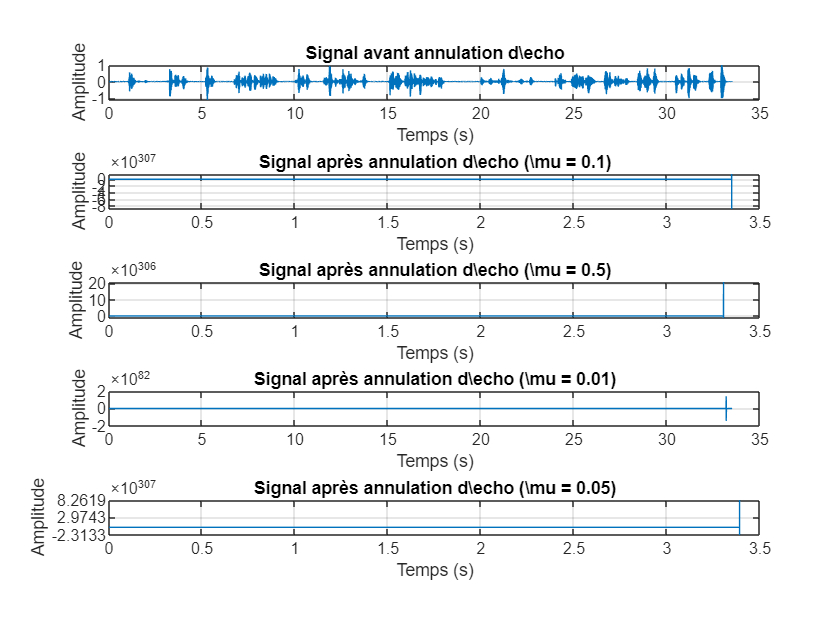

% Plot the signals in subplots
warning('off', 'all');  % Turn off all warnings

t = (0:length(dialogue)-1)/Fs;

figure;
% Plot original signal (dialogue)
subplot(5, 1, 1);
plot(t, dialogue);
title('Signal avant annulation d\echo');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (for mu = 0.1)
subplot(5, 1, 2);
plot(t, x_echo_canceled0);
title('Signal après annulation d\echo (\mu = 0.1)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (for mu = 0.5)
subplot(5, 1, 3);
plot(t, x_echo_canceled1);
title('Signal après annulation d\echo (\mu = 0.5)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (for mu = 0.01)
subplot(5, 1, 4);
plot(t, x_echo_canceled2);
title('Signal après annulation d\echo (\mu = 0.01)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;

% Plot signal after echo cancellation (for mu = 0.05)
subplot(5, 1, 5);
plot(t, x_echo_canceled3);
title('Signal après annulation d\echo (\mu = 0.05)');
xlabel('Temps (s)');
ylabel('Amplitude');
grid on;